## **Tarea Nº1: **

# **Procesamiento y Reconstrucción de Imágenes Médicas**

#### Universidad Técnica Federico Santa Maria

#### Departamento de Informatica - CSSJ - CC

#### ENUNCIADO

**a) Interpolación Trilineal (20 pts): **La siguiente página de Wikipedia ([https://acortar.link/q9pEiw](https://acortar.link/q9pEiw)), muestra matemáticamente como se puede realizar la Interpolación Trilineal. Desarrolle su propio código en forma de función de MATLAB, que reciba como entrada una imagen 3D, y un factor de escalamiento. Por ejemplo ***“im_out = trilineal_XX_YY(im_in, factor)”***, donde: 

- **XX_YY** = iniciales del nombre y apellido de los/as integrantes del grupo. 

- **im_in** = es el volumen de entrada. 

- **factor** = factor de escalamiento que va entre 0.05 < factor < 2 para este caso. 

El factor de escalamiento quiere decir que cuando factor tenga un valor de 0.5, mi imagen de salida tendrá un 50% del tamaño original, cuando tenga un valor de 2 la imagen de salida debe tener el doble del tamaño de la imagen original.  El código debe funcionar para cualquier rango de valores entre 0.05 y 2.

Genere una sección de “Help” en su función de MATLAB, donde describa brevemente lo que hace su código y adicionalmente debe definir los inputs, outputs, y incluir un ejemplo de ejecución de su código. 

***No se pueden usar las funciones de interpolación de Matlab, debe desarrollar su propio código***.

% Ejemplo de mi implementacion de la Interpolacion Trilinear
im_in = rand(50,50,50);
factor = 1.2

factor = 1.2000

resultado_trilineal = trilineal_MS_JG(im_in, factor);

**b) Reconstrucción de imágenes (20pts):** usted dispone de 2 imágenes que se encuentran dañadas con artefactos que son fácilmente visible en su espacio k.

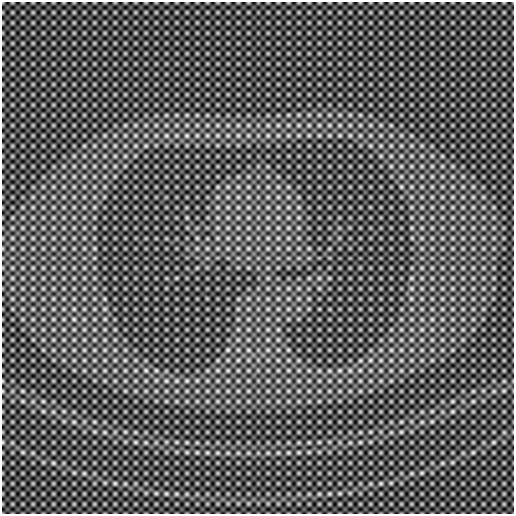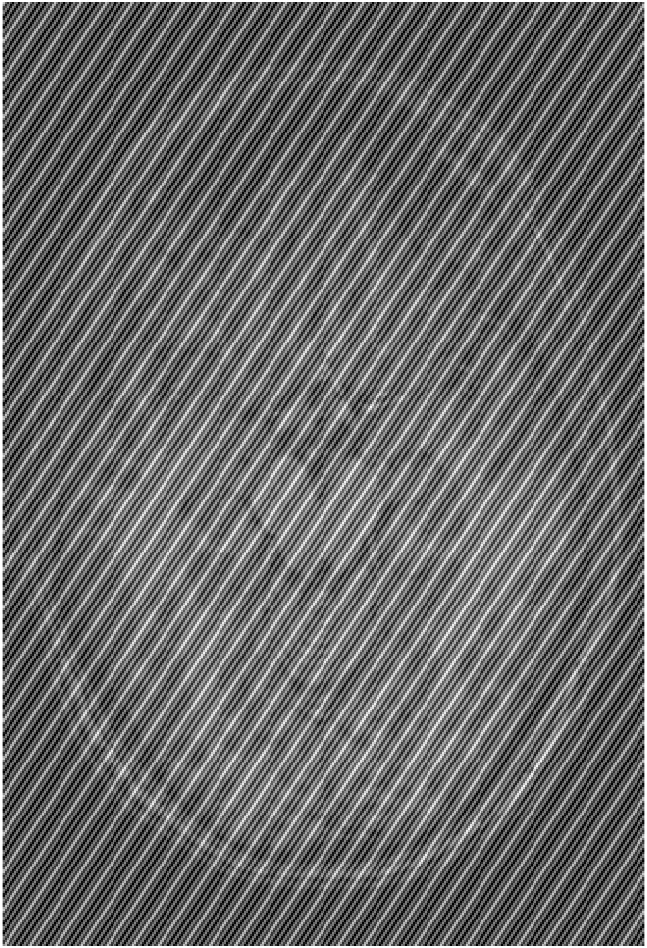

Implemente la estrategia que usted estime conveniente para poder corregir este problema y reconstruir la imagen lo mejor posible. Describa detalladamente que estrategia siguió. ***No está autorizado de usar las funciones de Matlab, ni para corregir la imagen, ni reconstruir la imagen, debe desarrollar su propio código (Usted puede hacer uso de códigos que desarrollamos en clases) ***

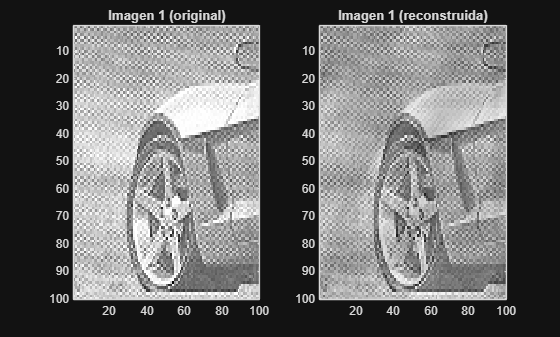

% Carga la primera imagen desde la ruta especificada
imagen_uno = imread('imagenes/t1b1.png');
imagen_dos = imread('imagenes/t1b2.png');

% Luego verifica si las imagenes estan en RGB, ya que en el
% curso acostumbramos a trabajar con imagenes monocromaticas

% Para la imagen uno
if ndims(imagen_uno) == 3
    imagen_uno = double(imagen_uno);
    imagen_uno = 0.2989 * imagen_uno(:,:,1) + ...
        0.5870 * imagen_uno(:,:,2) + ...
        0.1140 * imagen_uno(:,:,3);
else
    imagen_uno = double(imagen_uno);
end

% Para la imagen dos
if ndims(imagen_dos) == 3
    imagen_dos = double(imagen_dos);
    imagen_dos = 0.2989 * imagen_dos(:,:,1) + ...
        0.5870 * imagen_dos(:,:,2) + ...
        0.1140 * imagen_dos(:,:,3);
else
    imagen_dos = double(imagen_dos);
end

% Ejecuta la funcion en la primera y segunda imagen
resultado_uno = reconstruccion(imagen_uno);
resultado_dos = reconstruccion(imagen_dos);

% Crea un grafico para las imagenes originales
% y su posterior recontruccion usando el algoritmo

% Grafico para la primera imagen
figure;
subplot(1,2,1);
imagesc(imagen_uno);
colormap gray;
title('Imagen 1 (original)');

subplot(1,2,2);
imagesc(resultado_uno);
colormap gray;
title('Imagen 1 (reconstruida)');

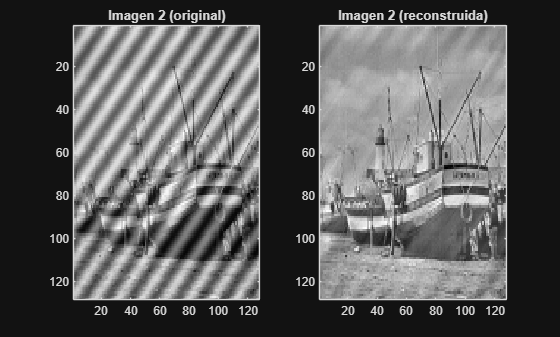

% Grafico para la segunda imagen
figure;
subplot(1,2,1);
imagesc(imagen_dos);
colormap gray;
title('Imagen 2 (original)');

subplot(1,2,2);
imagesc(resultado_dos);
colormap gray;
title('Imagen 2 (reconstruida)');

**c) Retroproyección (20 pts):** Usted dispone de los siguientes sinogramas, de dos imágenes desconocidas. 

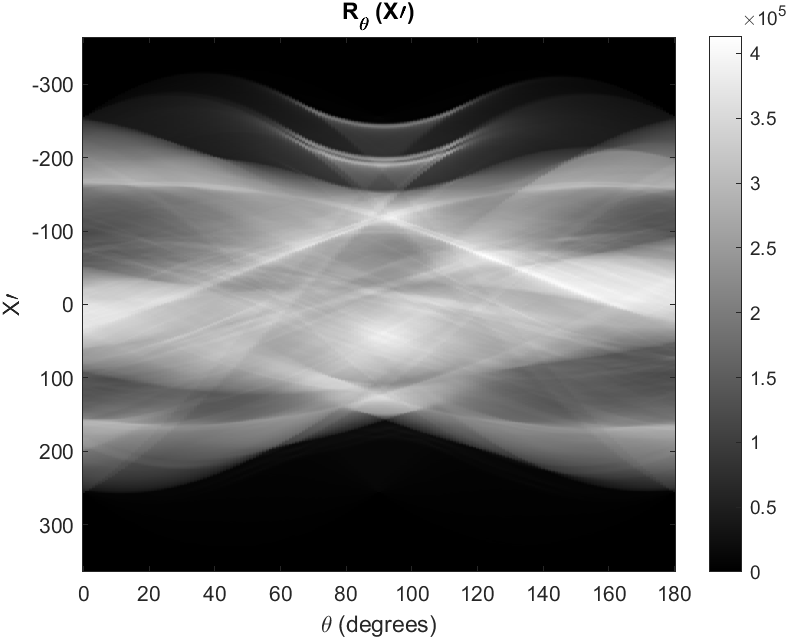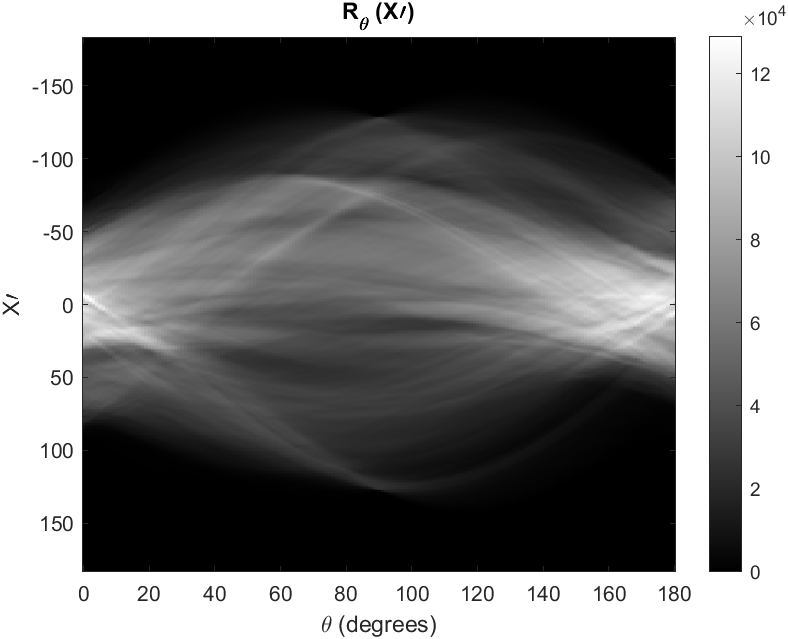

Realice la reconstrucción de la imagen original de cada uno de ellos usando retroproyección con y sin filtrar. Adicionalmente a partir de sus retroproyecciones filtradas, reconstruya la imagen resultante usando la transformada de fourier. ***No se pueden usar las funciones de la transformada de radón o iradon de Matlab, debe desarrollar su propio código. (Si esta permitido usar funciones de rotación en caso de necesitar y las funciones de la transformada de Fourier para filtrar las señales que se usaran posteriormente en cada retroproyección).***

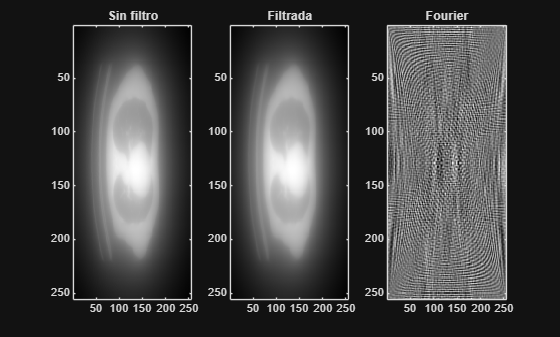

% Cargar sinograma
sinograma = imread('imagenes/t1c1.png');
sinograma = double(sinograma);

% Ejecuta la funcion de reconstruccion, la cual genera la retroproyeccion
% con filtrar, sin filtrar y con la transformada de Fourier
[sin_filtro, filtrada, fourier] = retroproyeccion(sinograma);

% Mostrar resultados en graficos
figure;

subplot(1,3,1);
imagesc(sin_filtro); colormap gray;
title('Sin filtro');

subplot(1,3,2);
imagesc(filtrada); colormap gray;
title('Filtrada');

subplot(1,3,3);
imagesc(fourier); colormap gray;
title('Fourier');

% Cargar sinograma
sinograma = imread('imagenes/t1c2.png');
sinograma = double(sinograma);

% Definir ángulos
num_angulos = size(sinograma, 2);
angulos = linspace(0, 180, num_angulos);

% Ejecutar reconstrucción
[sin_filtro, filtrada, fourier] = retroproyeccion(sinograma, angulos);

Error using retroproyeccion
Too many input arguments.


% Mostrar resultados
figure;

subplot(1,3,1);
imagesc(sin_filtro); colormap gray;
title('Sin filtro');

subplot(1,3,2);
imagesc(filtrada); colormap gray;
title('Filtrada');

subplot(1,3,3);
imagesc(fourier); colormap gray;
title('Fourier');

**d) Reconstrucción de imágenes paralelas:** A partir de la imagen de cerebro *m.mat *y las sensibilidades de las bobinas entregadas en *C.mat*, genere la imagen obtenida por cada bobina y realice lo siguiente:

**d.1) (5 pts)** Reconstruya la imagen a partir de las múltiples bobinas, utilizando la ecuación de suma de cuadrados.  


$$m\left(r\right)=\sqrt{\sum_{i=1}^{N_c } |m_i \left(r\right)|^2 }$$


load('m.mat'); % espera variable m (si contiene k-space, cambiar nombre según corresponda)
load('C.mat'); % espera variable C (sensitivities), tamaño [nx ny nCoils] o similar

% Intentar deducir variables
if exist('m','var')
    img = m;
elseif exist('M','var')
    img = M;
else
    error('No se encontró variable imagen en m.mat con nombre ''m'' o ''M''.');
end

% Asegurar que img sea imagen en el dominio de la imagen. 
% Si img es k-space (4D o 3D con coils), detectarlo por tamaño y transformar.
% Aquí asumimos img es imagen 2D (nx x ny). Si es k-space, aplicar ifft2.
% Detectar si img es complejo y si tiene una dimensión extra (coils)
dims = ndims(img);
if dims == 2 || (dims == 3 && size(img,3) == 1)
    % ya es imagen única
    baseImg = squeeze(img);
elseif dims == 3 && size(img,3) > 1

    baseImg = zeros(size(img), 'like', img);
    for c = 1:size(img,3)
        baseImg(:,:,c) = ifftshift(ifft2(fftshift(img(:,:,c))));
    end
else
    error('Formato de imagen no esperado.');
end

% Cargar sensitivities
if exist('C','var')
    S = C;
elseif exist('sens','var')
    S = sens;
else
    error('No se encontró variable sensibilidades en C.mat con nombre ''C'' o ''sens''.');
end

% Asegurar que S tenga dimensiones [nx ny nCoils]
if ndims(S) == 2
    S = S(:,:,1);
end

[nx, ny, nCoilsS] = size(S);
[nx2, ny2, nCoilsImg] = size(baseImg);

% Si baseImg no tiene dimensión de coils, expandir para multiplicar con S
if ndims(baseImg) == 2
    if nx~=nx2 || ny~=ny2
        error('Dimensiones de imagen y sensibilidades no coinciden.');
    end
    % Imagen única: generar la señal por coil multiplicando por el mapa de sensibilidad
    imgCoils = zeros(nx, ny, nCoilsS, 'like', baseImg);
    for c = 1:nCoilsS
        imgCoils(:,:,c) = baseImg .* S(:,:,c);
    end
else
    % baseImg tiene dimensión de coils; si coincide con nCoilsS, usar elemento a elemento
    if nx~=nx2 || ny~=ny2
        error('Dimensiones espaciales de imagen y sensibilidades no coinciden.');
    end
    if nCoilsImg == nCoilsS
        imgCoils = baseImg .* S;
    else
        % Si número de coils difiere, asumir baseImg es imagen única replicada por coil
        imgCoils = zeros(nx, ny, nCoilsS, 'like', baseImg);
        imgOnly = sum(baseImg,3) / nCoilsImg;
        for c = 1:nCoilsS
            imgCoils(:,:,c) = imgOnly .* S(:,:,c);
        end
    end
end

% Mostrar imagen obtenida por cada bobina y su módulo y fase
figure('Name','Imágenes por bobina','NumberTitle','off');
nPlots = nCoilsS;
cols = ceil(sqrt(nPlots));
rows = ceil(nPlots/cols);
for c = 1:nCoilsS
    subplot(rows, cols, c);
    imagesc(abs(imgCoils(:,:,c))); axis image off; colormap gray;
    title(sprintf('Bobina %d | |I|_{max}=%.2f', c, max(abs(imgCoils(:,:,c)),[],'all')));
end

sos = sqrt(sum(abs(imgCoils).^2, 3));
figure('Name','Reconstrucción SOS','NumberTitle','off');
imagesc(sos); axis image off; colormap gray;
title('Reconstrucción Sum-of-Squares');

**d.2) (5 pts) **Reconstruya la imagen a partir de las múltiples bobinas, utilizando la ecuación de combinación de sensibilidad pesadas. 


$$m\left(r\right)=\frac{\sum_{i=1}^{N_c } c_i^* \left(r\right)m_{i\left(r\right)} }{\sqrt{\sum_{i=1}^{N_c } |c_i \left(r\right)|^2 }}$$


den = sum(abs(S).^2, 3);
num = zeros(nx, ny, 'like', imgCoils);
for c = 1:nCoilsS
    num = num + conj(S(:,:,c)) .* imgCoils(:,:,c);
end
den(den==0) = eps;
sens_comb = num ./ den;
figure('Name','Reconstrucción por combinación sensible','NumberTitle','off');
imagesc(abs(sens_comb)); axis image off; colormap gray;

**d.3) (10 pts)** Aplique el método de reconstrucción SENSE de imágenes paralelas visto en el código de ejemplo de Matlab para un submuestreo x4, x6, x8. Muestre en pantalla las imágenes de cada una de las bobinas sub-muestreadas y también entregue la imagen reconstruida final. Comente acerca de los resultados obtenidos. 

%Escriba su Código aca


**d.4) (20 pts) **Finalmente investigue acerca del método de reconstrucción GRAPPA (Generalized autocalibrating partially parallel acquisitions), e impleméntelo a cada una de las imágenes de las bobinas con submuestreo x2, y reconstruya la imagen resultante con la ecuación de combinación de sensibilidad pesadas. Puede mirar el paper original de GRAPPA, para orientarse ([https://doi.org/10.1002/mrm.10171](https://doi.org/10.1002/mrm.10171)). 

%Escriba su Código aca